# Spectral Analysis - SMURF data

Jess Hopf

2021

* Channel islands backgournd: https://channelislands.noaa.gov/marineres/welcome.html

### Requires:

- MATLAB 2020b (or higher)

- Gamm plotting function: https://www.mathworks.com/matlabcentral/fileexchange/54465-gramm-complete-data-visualization-toolbox-ggplot2-r-like

- SMURFData_select2021.mat (data)

- Func_SpectralAnalysis (spectral analysis function)

### Read in Data

% load the pre-cleaned SMURF data
load("Data/SMURFData_select2021.mat")


### Plotting SMURF data

Standardised number of recruits:

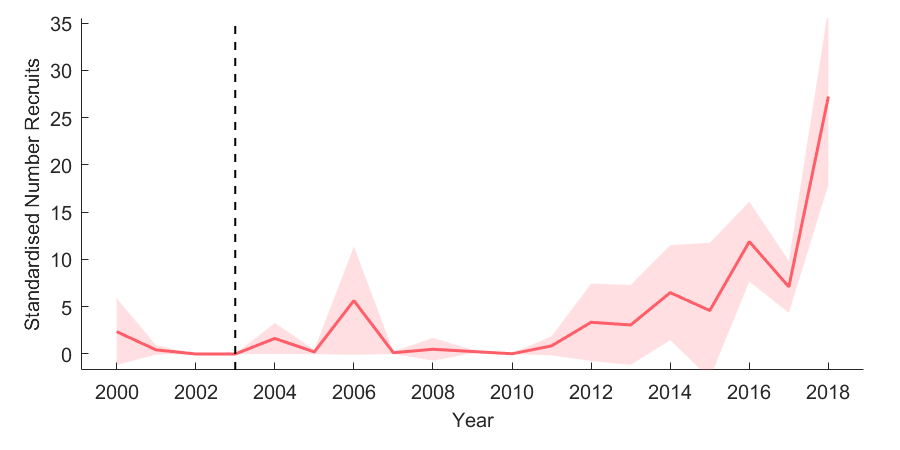

clear g
figure('Position',[10,10,600,300]);
g = gramm('x',SMURFdata.Year,'y',SMURFdata.NumFishSt);
g.stat_summary('type','std','geom','area');
g.set_names('x','Year','y','Standardised Number Recruits','row',''); 
g.geom_vline('xintercept',2003);
g.draw();

As above, but log transformed

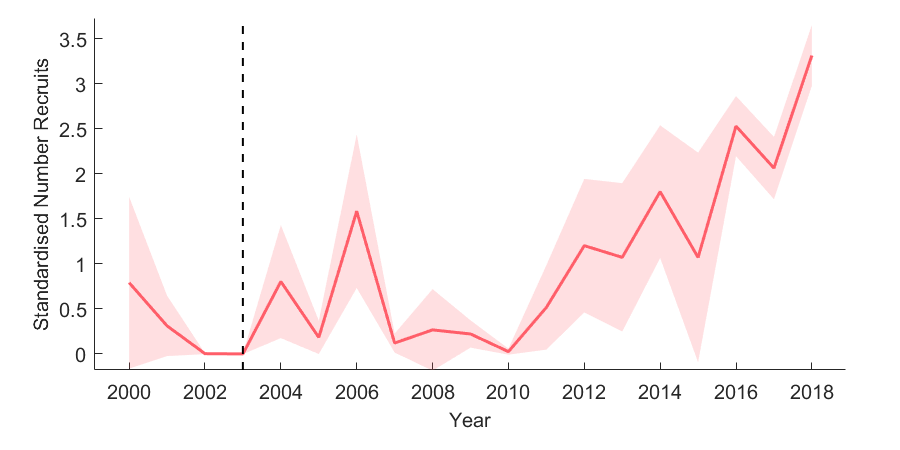

% log + 1 transformed
clear g
figure('Position',[10,10,600,300]);
g = gramm('x',SMURFdata.Year,'y',log(SMURFdata.NumFishSt+1));
g.stat_summary('type','std','geom','area');
g.set_names('x','Year','y','Standardised Number Recruits','row','');
g.geom_vline('xintercept',2003);
g.draw();

Plot each site individually

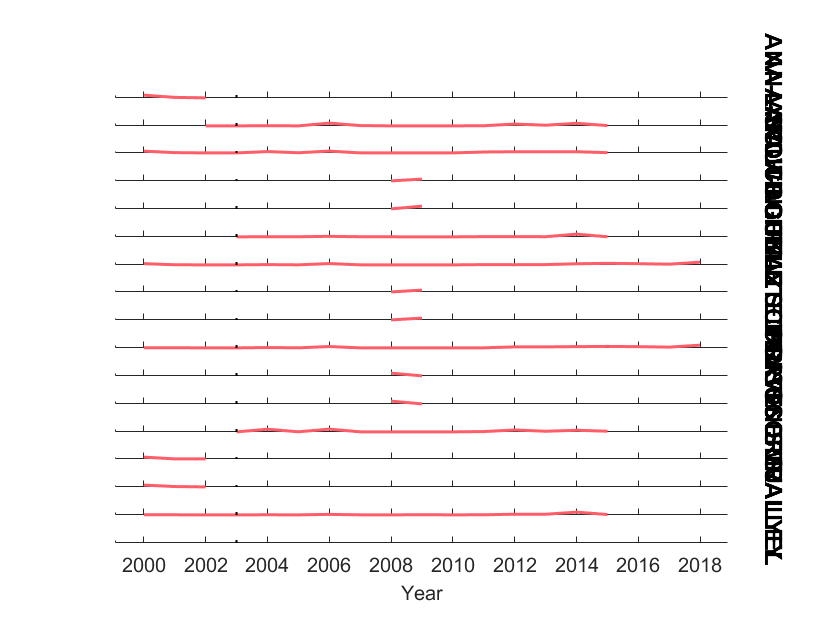

% plot individual sites
clear g
figure();
g = gramm('x',SMURFdata.Year,'y',SMURFdata.NumFishSt); %, 'color', SDEastIsPCLA.SITE);
g.geom_line();
g.facet_grid(SMURFdata.SITE,[],"scale","free_y");
g.set_names('x','Year','y','Total Number Recruits','row','');
g.geom_vline('xintercept',2003);
g.draw();

### Time Series Data

Set-up time series data.

% get the number of data points (i.e. number of years counted) for each site
SMURFdataNumEl = grpstats(SMURFdata, {'Species','Island','SITE'},'numel');

% get sites with >=10 data points
SitesKeep = SMURFdataNumEl.SITE(SMURFdataNumEl.numel_Year > 9);

% Filter data 
SMURFdataSites = SMURFdata(ismember(SMURFdata.SITE,SitesKeep),:);

% Check years for each site
unstack(SMURFdataSites,'NumFishSt','Year',...
        'GroupingVariables',{'Species','SITE'},'AggregationFunction',@(x) numel(unique(x))) 

ans = 7×21 table
                                     Species      SITE       x2000    x2001    x2002    x2003    x2004    x2005    x2006    x2007    x2008    x2009    x2010    x2011    x2012    x2013    x2014    x2015    x2016    x2017    x2018
                                     _______    _________    _____    _____    _____    _____    _____    _____    _____    _____    _____    _____    _____    _____

### Spectral Analysis

Create a timeseries object & run spectral analysis to see if there is signifincant periodicity in the data.

% sum together for each year
SMURFdataPool = grpstats(SMURFdata(:,{'Species','Year','NumFishSt'}), ...
                           {'Species','Year'},'sum');

% standardise by number of sites in a given year
SMURFdataPool.NormNumFishSt = SMURFdataPool.sum_NumFishSt./SMURFdataPool.GroupCount;

% the above could also have been achieved by taking the mean at each year...

% spectral analysis
SAdata = log(SMURFdataPool.NormNumFishSt(SMURFdataPool.Species == 'PCLA')+1);
SAtime = SMURFdataPool.Year(SMURFdataPool.Species == 'PCLA');
[period, AS, PS,tsDTstd] = Func_SpectralAnalysis(SAdata, SAtime, NaN, NaN);
% Get values; 
% AS gives the amplitude spectrum - to be used in the model
% PS give the power spectrum = variance 
[period', AS, PS]

ans =        Inf    3.1055    4.8221
   18.0000    0.8830    0.3898
    9.0000    0.3271    0.0535
    6.0000    0.6162    0.1899
    4.5000    0.1861    0.0173
    3.6000    0.1374    0.0094
    3.0000    0.3338    0.0557
    2.5714    0.2551    0.0325
    2.2500    0.4303    0.0926
    2.0000    0.4619    0.1067


% sum of PS(2:end) = variance of time series (which has been normalised) 
sum(PS(2:end))

ans = 0.9474


% sum of all except sig peak vaules give proportion of variance that is
% random noise
sum(PS(~ismember(period,[Inf,6,3])))

ans = 0.7018

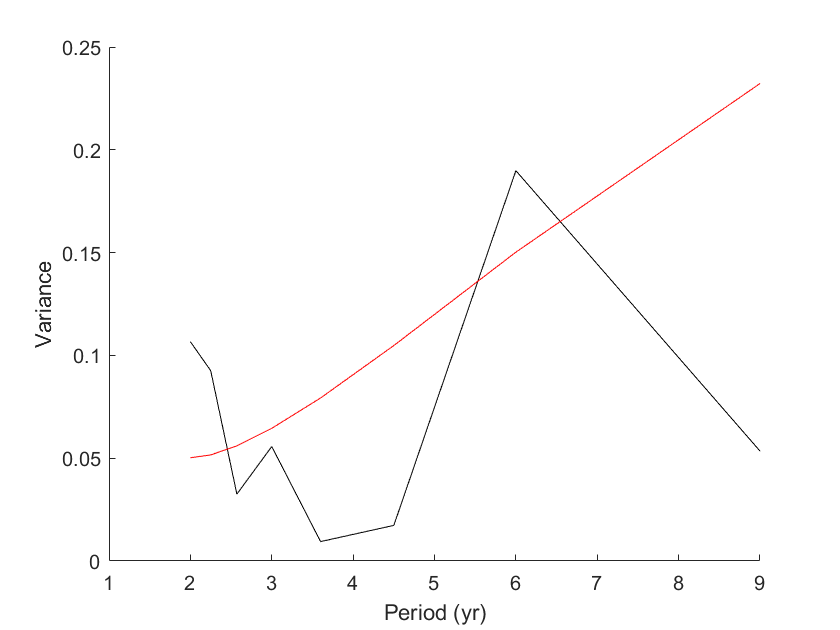


% add axis lables (go to 10 since half length of time series, actually its only 9)
xlim([1,9])
xlabel('Period (yr)')
ylabel('Variance')
hold off

Plot detrended data

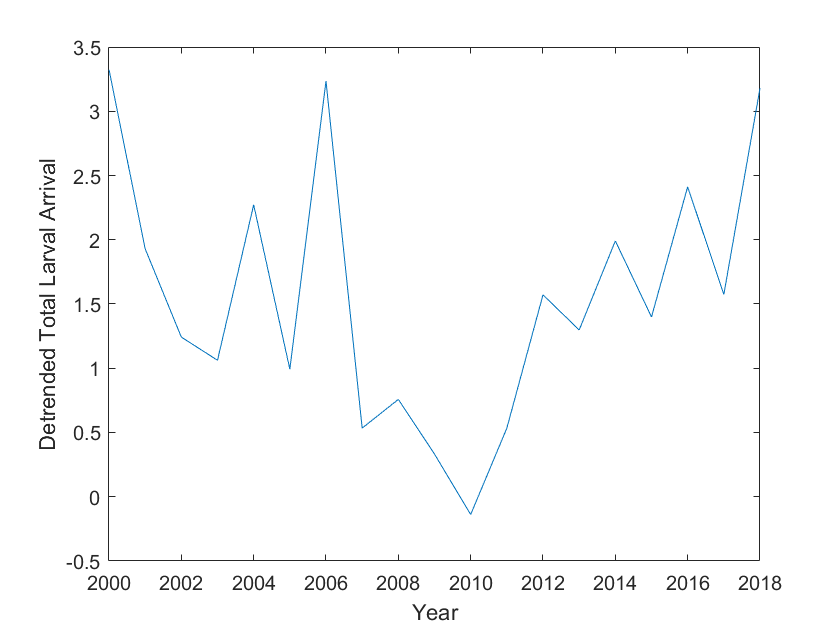

figure
plot(2000:2018, tsDTstd)
xlabel('Year')
ylabel('Detrended Total Larval Arrival')

Correlations between sites

% make into a matrix for cross-corr
SDEast_TS = unstack(SMURFdataSites,'NumFishSt','SITE','GroupingVariables',{'Year'});

% replace NaN with zeros to pad out and make even lengthts
SDEast_TS = fillmissing(SDEast_TS,'constant',0)

SDEast_TS = 19×8 table
                                   Year    ANA_SOUTH     ANA_WIN       GULL         HAZ          PEL         SCORP       VALLEY  
                                   ____    _________    _________    ________    _________    _________    _________    _________

    Anacapa_ANA-SOUTH_2002_PCLA    2002            0    0.0089286           0     0.013255    0.0084935            0    0.0030303
    Anacapa_ANA-SOUTH_2003_PCLA    2003            0            0           0    0.0019157     0.005291            0            0
    Anacapa_ANA-SOUTH_2004_PCLA    2004      0.22497       3.9046     0.18502       1.8255       3.8284       1.2829       0.2545
   

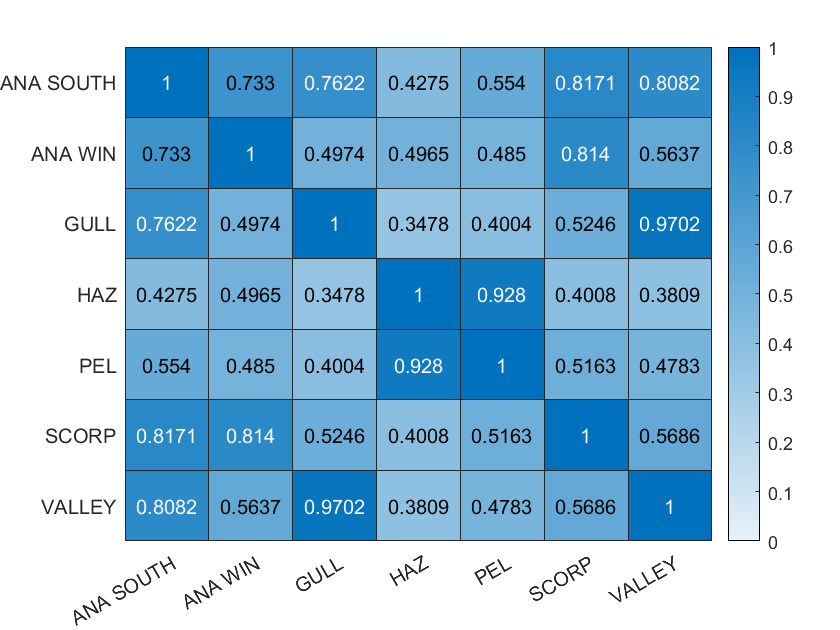


% convert table to matrix
SDEast_TSmat = table2array(SDEast_TS(:,2:end));

% get site names
sitesCC = SDEast_TS.Properties.VariableNames;
sitesCC = sitesCC(2:end);

% replace _
sitesCC(1:2) = [{'ANA SOUTH'}, {'ANA WIN'}];

% cross-correlation
maxlag = 0;
CC = xcorr(SDEast_TSmat,maxlag,'normalized');
CC = CC(maxlag+1:end,:);
CC = reshape(CC',size(SDEast_TSmat,2),size(SDEast_TSmat,2),maxlag+1);

% plot
for i = 1:maxlag+1
figure
heatmap(sitesCC,sitesCC,CC(:,:,i),'ColorLimits',[0,1])
end

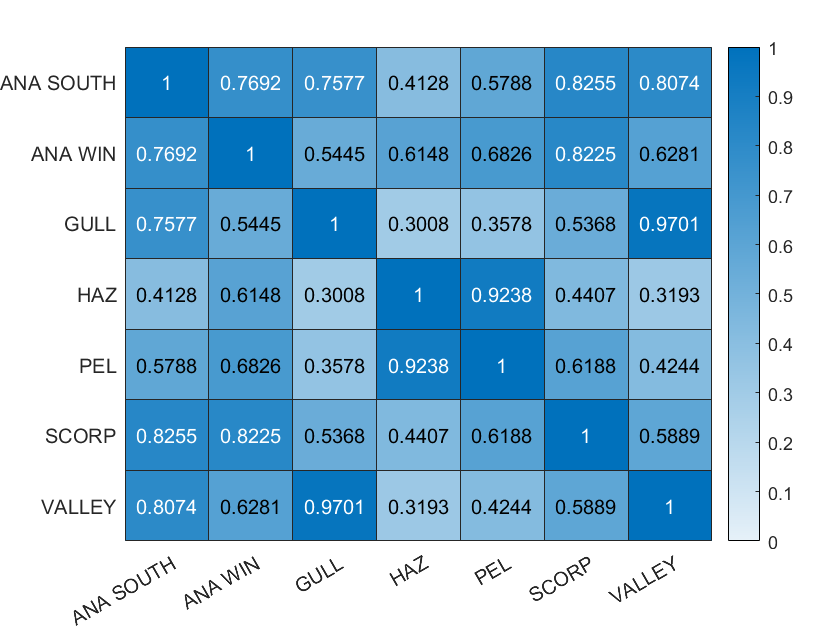


% detrend the redo CC
for i = 1:size(SDEast_TSmat,2)
    SDEast_TS_model = fitglm(SDEast_TS(:,[1,i+1]));
    SDEast_TSmat_DT(:,i) = mean(SDEast_TSmat(:,i)) + SDEast_TSmat(:,i) - predict(SDEast_TS_model);
end

% cross-correlation
maxlag = 0;
CCDT = xcorr(SDEast_TSmat_DT,maxlag,'normalized');
CCDT = CCDT(maxlag+1:end,:);
CCDT = reshape(CCDT',size(SDEast_TSmat_DT,2),size(SDEast_TSmat_DT,2),maxlag+1);

% plot
for i = 1:maxlag+1
figure
heatmap(sitesCC,sitesCC,CCDT(:,:,i),'ColorLimits',[0,1])
end

Check Gull and Valley not influenceing result:

SMURFdataEast = grpstats(SMURFdata(ismember(SMURFdata.Island,{'Anacapa','Santa Cruz'}) & ...
    ~ismember(SMURFdata.SITE,{'GULL','VALLEY'}),...
                        {'Species','Year','NumFishSt'}), ...
                           {'Species','Year'},'sum');

% standardise by number of sites in a given year
SMURFdataEast.NormNumFishSt = SMURFdataEast.sum_NumFishSt./SMURFdataEast.GroupCount;

% spectral analysis
% SAdata = log10(SMURFdataPool.NormNumFishSt(SMURFdataPool.Species == 'PCLA')+1);
SAdata = log(SMURFdataEast.NormNumFishSt(SMURFdataEast.Species == 'PCLA')+1);
SAtime = SMURFdataEast.Year(SMURFdataEast.Species == 'PCLA');
[period, AS, PS] = Func_SpectralAnalysis(SAdata, SAtime, NaN, NaN);
% Get values; 
% AS gives the amplitude spectrum - to be used in the model
% PS give the power spectrum = variance 
[period', AS, PS]

ans =        Inf    3.1508    4.9637
   18.0000    0.8217    0.3376
    9.0000    0.3469    0.0602
    6.0000    0.6407    0.2052
    4.5000    0.1895    0.0180
    3.6000    0.1866    0.0174
    3.0000    0.3658    0.0669
    2.5714    0.2526    0.0319
    2.2500    0.4412    0.0973
    2.0000    0.4752    0.1129


% sum of PS(2:end) = variance of time series (which has been normalised) 
sum(PS(2:end))

ans = 0.9474


% sum of all except sig peak vaules: gives proportion of variance that is
% random noise
sum(PS(~ismember(period,[Inf,6,3])))

ans = 0.6752

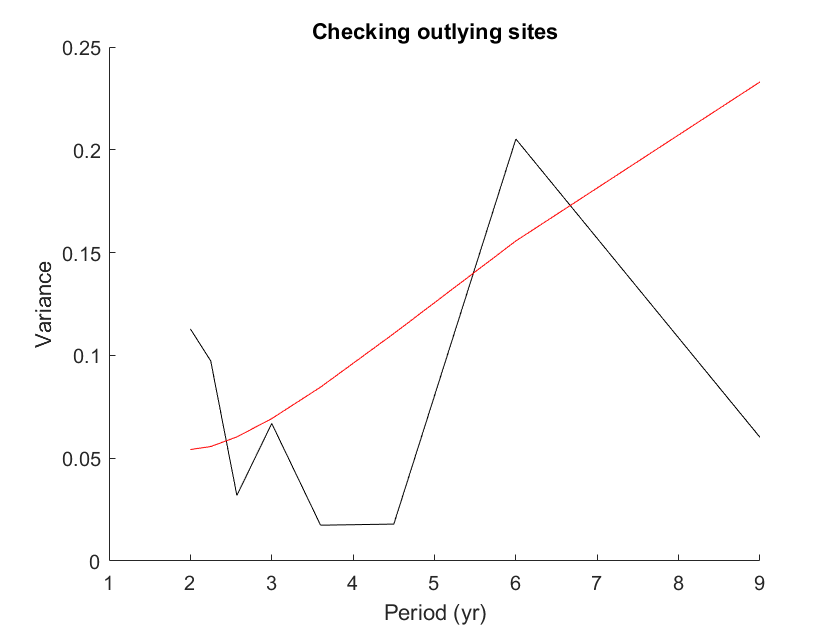


% add axis lables (go to 10 since half length of time series, actually its only 9)
xlim([1,9])
xlabel('Period (yr)')
ylabel('Variance')
title('Checking outlying sites')
hold off

Looks good!